Kt = 1.57e-2;
Ke = Kt;
Ra = 8;
B = 2.52e-3;
J = 9.85e-3;

sysM = ss(tf(Ra,[Ra*J Ke*Kt+Ra*B 0]))

sysM =
 
  A = 
           x1      x2
   x1  -0.259       0
   x2     0.5       0
 
  B = 
       u1
   x1  16
   x2   0
 
  C = 
          x1     x2
   y1      0  12.69
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



sysE = ss(tf((Kt/Ra)))

sysE =
 
  D = 
             u1
   y1  0.001962
 
Static gain.




SYS=series(sysE,sysM)

SYS =
 
  A = 
           x1      x2
   x1  -0.259       0
   x2     0.5       0
 
  B = 
           u1
   x1  0.0314
   x2       0
 
  C = 
          x1     x2
   y1      0  12.69
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



s=tf('s')

s =
 
  s
 
Continuous-time transfer function.



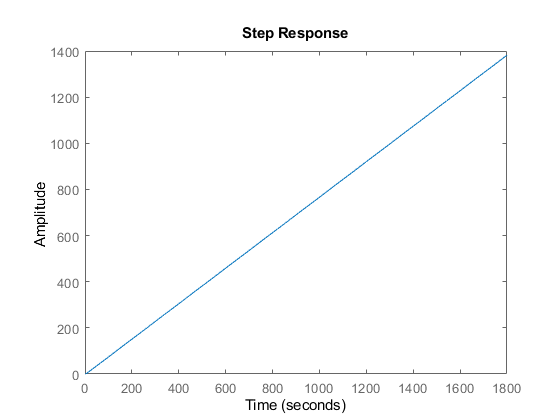


step(SYS)